Plot Physio by Trial and update the Plot by Buttonclick

TO-DO:

- *1. Load in Physio, Eyetracking and Event data for one participant*

- *2. Change Event data so that it resembles the format of the other data points (CS+ 1.1, CS- 1.0)*

- 3. Create plots for each trial

- 4. Create just one plot that can be scrolled in by using a button or scale

- 5. Code a preface that allows you to acess other participants/sessions

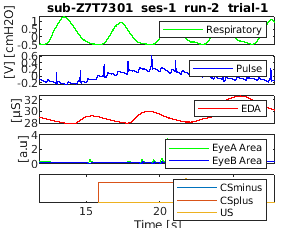

%% Load physio, eyetracking and event data for one participant
script_init_study7;

fn_events = '/media/diskEvaluation/Evaluation/sfb1280a05study7/rawdata/sub-Z7T7301/ses-1/func/sub-Z7T7301_ses-1_task-fear_acq-stxtr1620_run-2_events.tsv';
fn_eyetrack = '/media/diskEvaluation/Evaluation/sfb1280a05study7/rawdata/sub-Z7T7301/ses-1/func/sub-Z7T7301_ses-1_task-fear_acq-stxtr1620_run-2_eyetrack.tsv.gz';
fn_physio = '/media/diskEvaluation/Evaluation/sfb1280a05study7/rawdata/sub-Z7T7301/ses-1/func/sub-Z7T7301_ses-1_task-fear_acq-stxtr1620_run-2_physio.tsv.gz';


global curr_idx;%#ok<*GVMIS>
global max_idx;
global ax_events;
global ax_eyetrack;
global ax_eda;
global ax_pulse;
global ax_resp;
global t_events;
global bf;

curr_idx = 1;
t_physio = essbids_readTsv(fn_physio);
t_physio.time = t_physio.Properties.CustomProperties.Time;

t_eyetrack = essbids_readTsv(fn_eyetrack);
t_eyetrack.time = t_eyetrack.Properties.CustomProperties.Time;

t_events = essbids_readTsv(fn_events);
t_eventmarkers = table();

bf = essbids_parseLabel(fn_physio);
figTitle = sprintf('sub-%s  ses-%s  run-%s  trial-',bf.sub,bf.ses,bf.run);

preal_a = zeros(numel(t_events(:,1))*4,3);
for idx = 1:numel(t_events(:,1))
    idx_bf = (idx*4)-3;
    idx_on = (idx*4)-2;
    idx_off = (idx*4)-1;
    idx_nx = idx*4;
    c_trial_type = t_events.trial_type(idx);
     if isequal(c_trial_type{1},'CSminus')
        preal_a(idx_bf,:) = [(t_events.onset(idx)-0.001),0,t_events.trial_index(idx)];
        preal_a(idx_on,:) = [t_events.onset(idx),1,t_events.trial_index(idx)];
        preal_a(idx_off,:) = [t_events.onset(idx)+t_events.duration(idx),1,t_events.trial_index(idx)];
        preal_a(idx_nx,:) = [t_events.onset(idx)+t_events.duration(idx)+0.001,0,t_events.trial_index(idx)];
     elseif isequal(c_trial_type{1},'CSplus')
        preal_a(idx_bf,:) = [(t_events.onset(idx)-0.001),0,t_events.trial_index(idx)];
        preal_a(idx_on,:) = [t_events.onset(idx),1.1,t_events.trial_index(idx)];
        preal_a(idx_off,:) = [t_events.onset(idx)+t_events.duration(idx),1.1,t_events.trial_index(idx)];
        preal_a(idx_nx,:) = [t_events.onset(idx)+t_events.duration(idx)+0.001,0,t_events.trial_index(idx)];
     elseif isequal(c_trial_type{1},'US')
        preal_a(idx_bf,:) = [(t_events.onset(idx)-0.001),0,t_events.trial_index(idx)];
        preal_a(idx_on,:) = [t_events.onset(idx),1.3,t_events.trial_index(idx)];
        preal_a(idx_off,:) = [t_events.onset(idx)+t_events.duration(idx),1.3,t_events.trial_index(idx)];
        preal_a(idx_nx,:) = [t_events.onset(idx)+t_events.duration(idx)+0.001,0,t_events.trial_index(idx)];
     end
end

t_eventmarkers.timestamps = preal_a(:,1);
t_eventmarkers.marker_value = preal_a(:,2);
t_eventmarkers.trial_index = preal_a(:,3);
       
%% Plot Eventmarker

ax_events = subplot(5,2,9:10);
plot(t_eventmarkers.timestamps(t_eventmarkers.marker_value == 1 | t_eventmarkers.marker_value == 0),t_eventmarkers.marker_value(t_eventmarkers.marker_value == 1 | t_eventmarkers.marker_value == 0));
hold on
plot(t_eventmarkers.timestamps(t_eventmarkers.marker_value == 1.1 | t_eventmarkers.marker_value == 0),t_eventmarkers.marker_value(t_eventmarkers.marker_value == 1.1 | t_eventmarkers.marker_value == 0));

if nnz(t_eventmarkers.marker_value == 1.3) > 1
    plot(t_eventmarkers.timestamps(t_eventmarkers.marker_value == 1.3 | t_eventmarkers.marker_value == 0), t_eventmarkers.marker_value(t_eventmarkers.marker_value == 1.3 | t_eventmarkers.marker_value == 0));
    legend('CSminus','CSplus','US');
else
    legend('CSminus','CSplus');
end

hold off
ax_events.XLim = [t_events.onset(1)-4,t_events.onset(1)+t_events.duration(1)+6];
ax_events.YLim = [0,1.5];
ax_events.YTick = [];
xlabel("Time [s]");

%% Plot Eyetrack Area
ax_eyetrack = subplot(5,2,7:8);
plot(t_eyetrack.time,t_eyetrack.EyeA_Area,'Color','green');
hold on 
plot(t_eyetrack.time,t_eyetrack.EyeB_Area,'Color','blue');
legend('EyeA Area','EyeB Area');
hold off
ax_eyetrack.XLim = [t_events.onset(1)-4,t_events.onset(1)+t_events.duration(1)+6];
ax_eyetrack.XTick = 0;
ylabel("[a.u]");

%% Plot EDA
ax_eda = subplot(5,2,5:6);
plot(t_physio.time,t_physio.skinconductance,'Color','red');
legend('EDA');
ax_eda.XLim = [t_events.onset(1)-4,t_events.onset(1)+t_events.duration(1)+6];
ax_eda.XTick = 0;
ylabel('[µS]');

%% Plot Pulseoxy
ax_pulse = subplot(5,2,3:4);
plot(t_physio.time,t_physio.pulseoximeter,'Color','blue');
legend('Pulse');
ax_pulse.XLim = [t_events.onset(1)-4,t_events.onset(1)+t_events.duration(1)+6];
ax_pulse.XTick = 0;
ylabel('[V]');

%% Plot Respiratory
ax_resp = subplot(5,2,1:2);
plot(t_physio.time,t_physio.respiratory,'Color','green');
legend('Respiratory');
ax_resp.XLim = [t_events.onset(1)-4,t_events.onset(1)+t_events.duration(1)+6];
ax_resp.XTick = 0;
ylabel("[cmH2O]");
title(string(figTitle) + string(t_events.trial_index(1)));

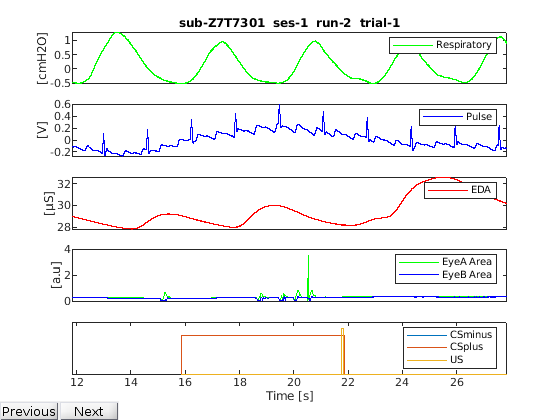

%% Buttons
button_prev = uicontrol("Style","pushbutton","String","Previous","Position",[0 0 60 20]);
button_prev.Callback = @prevPushButton;
button_continue = uicontrol("Style","pushbutton","String","Next","Position",[60 0 60 20]);

button_continue.Callback = @nxtPushButton;


Error using matlab.ui.Figure/set
Invalid or deleted object.

max_idx = numel(t_events.trial_index(:,1));
%% Button-Functions


function prevPushButton(~,~)
    global curr_idx;
    global ax_events;
    global ax_eyetrack;
    global ax_eda;
    global ax_pulse;
    global ax_resp;
    global t_events;
    global bf;
    cTemp = t_events.trial_type(curr_idx-1);
    sTrial = cTemp{1};

        if (curr_idx-1) < 1
            warning("The current trial selected is the last trial of this session.")
            return
        elseif isequal(sTrial,'US') && ~(curr_idx-1) == 0
            curr_idx = curr_idx - 1;
        end
        curr_idx = curr_idx-1;
        ax_resp.Title.String = sprintf('sub-%s  ses-%s  run-%s  trial-',bf.sub,bf.ses,bf.run)+string(t_events.trial_index(curr_idx));
        ax_events.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_eyetrack.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_eda.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_pulse.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_resp.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];

end
function nxtPushButton(~,~)
    global curr_idx;
    global max_idx;
    global ax_events;
    global ax_eyetrack;
    global ax_eda;
    global ax_pulse;
    global ax_resp;
    global t_events;
    global bf;
    cTemp = t_events.trial_type(curr_idx);
    sTrial = cTemp{1};
    
        if (curr_idx+1) > max_idx
            warning("The current trial selected is the last trial of this session.")
            return
        elseif isequal(sTrial,'US')
            curr_idx = curr_idx + 1; 
        end

        ax_resp.Title.String = sprintf('sub-%s  ses-%s  run-%s  trial-',bf.sub,bf.ses,bf.run)+string(t_events.trial_index(curr_idx));
%         uTitle = sprintf('sub-%s  ses-%s  run-%s  trial-',bf.sub,bf.ses,bf.run)+string(curr_idx);
%         set(hFig,'NumberTitle','off','Name',uTitle)

        ax_events.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_eyetrack.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_eda.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_pulse.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        ax_resp.XLim = [t_events.onset(curr_idx)-4,t_events.onset(curr_idx)+t_events.duration(curr_idx)+6];
        curr_idx = curr_idx +1;
    end